clc
clear
close all

## Initialization

N = 2;

### Joints

q = [1; pi/3; pi/3; 0; 0; 0];
dq = [0; 0; 0; 0; 0; 0];
ddq = [0; 0; 0; 0; 0; 0];
q = q(1:N);
dq = dq(1:N);
ddq = ddq(1:N);

### External wrench

he = zeros(N, 1);

### Friction

F = 5 * eye(N);

### Gravity

g = [0; 0; -9.82];

### Simulation time

time_span = linspace(0, 30, 1000);

## Load Robot Model

file_name = sprintf("ur5e/%i/Robot.mat", N);
robot = load(file_name);
robot = robot.robotUR5e;
robot.DataFormat = 'column';
robot.Gravity = g;

#### Simulation with robot

$\tau_{\mathrm{friction}} =F_v \dot{q}$, $\tau =0$


$$\begin{array}{l}
\tau -\tau_{\mathrm{friction}} =M\left(q\right)\ddot{q} +C\left(q,\dot{q} \right)+g\left(q\right)\\
\to \\
\ddot{q} ={M\left(q\right)}^{-1} \cdot \left(\tau -\tau_{\mathrm{friction}} -C\left(q,\dot{q} \right)-g\left(q\right)\right)
\end{array}$$


forwardDyn = @(q, dq) inv(robot.massMatrix(q)) * (-F * dq - robot.velocityProduct(q, dq) - robot.gravityTorque(q));


$$\begin{array}{l}
\tau -\tau_{\mathrm{friction}} =M\left(q\right)\ddot{q} +C\left(q,\dot{q} \right)+g\left(q\right)-\tau_{\mathrm{ext}} \\
\mathrm{where}\\
\tau_{\mathrm{ext}} =K\left(q_d -q\right)+D\left({\dot{q} }_d -\dot{q} \right)+M\left(q\right)\left({\ddot{q} }_d -\ddot{q} \right)\\
\tau -\tau_{\mathrm{friction}} =M\left(q\right)\ddot{q} +C\left(q,\dot{q} \right)+g\left(q\right)-\left(K\left(q_d -q\right)+D\left({\dot{q} }_d -\dot{q} \right)+M\left(q\right)\left({\ddot{q} }_d -\ddot{q} \right)\right)\\
\tau -\tau_{\mathrm{friction}} =M\left(q\right){\ddot{q} }_d +C\left(q,\dot{q} \right)+g\left(q\right)-\left(K\left(q_d -q\right)+D\left({\dot{q} }_d -\dot{q} \right)\right)\\
\to \\
{\ddot{q} }_d ={M\left(q\right)}^{-1} \cdot \left(\tau -\tau_{\mathrm{friction}} -C\left(q,\dot{q} \right)-g\left(q\right)+K\left(q_d -q\right)+D\left({\dot{q} }_d -\dot{q} \right)\right)
\end{array}$$


K = 8 * eye(N);
D = 5 * eye(N);

Desired $q$ and $\dot{q}$

q_d = [
    pi/3;
    pi/3
    ];
dq_d = [
    0;
    0
    ];

%forwardDyn = @(q, dq) inv(robot.massMatrix(q)) * (-F * dq - robot.velocityProduct(q, dq) - robot.gravityTorque(q) + K*(q_d - q) + D*(dq_d - dq));

odefun = @(t, y) [y(N+1:end);
    forwardDyn(y(1:N), y(N+1:end))];

tic
[~, y] = ode45(odefun, time_span, [q; dq]);
toc

Elapsed time is 5.892151 seconds.


Plot simulation

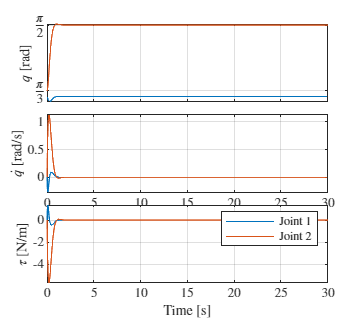

file_name = "Simulations/Robot_simluation.pdf";
plot_movement(time_span, y, D, file_name)

### Compute joint torques at a specific configuration

tau = robot.inverseDynamics(q, dq, ddq)

tau =     0.0000
   -8.4075


## Functions

### Plot output from simulation

function plot_movement(t, y, D, file_name)

Extract data from the simulation

[~, cols] = size(y);
sim_q = y(:, 1:cols/2);
sim_dq = y(:, (cols/2)+1:cols);
sim_tau = (-D * sim_dq')';

Configurate the figure

set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
fig = figure;
fig.Units = 'centimeters';
fig.Position(3) = 8; % width
fig.Position(4) = 7; % height

Plot simulation for $q$

subplot(6,1,1:2)
plot(t, sim_q)
ylabel('$q$ [rad]');
grid on
%ylim([-0.1, 1.8])
yticks([0, pi/3, pi/2])
yticklabels({'0', '$\frac{\pi}{3}$', '$\frac{\pi}{2}$'})
xticklabels({})

Plot simulation for $\dot{\;q}$

subplot(6,1,3:4)
plot(t, sim_dq)
grid on
xlabel("Time [s]")
%ylim([-1.2, 1.2])
ylabel('$\dot{q}$ [rad/s]')

Plot simulation for $\tau$

subplot(6,1,5:6)
plot(t, sim_tau)
grid on
xlabel("Time [s]")
%ylim([-6, 6])
ylabel('$\tau$ [N/m]')

Create legends

legend_labels = string([]);
for i = 1 : cols/2
    legend_labels(i) = sprintf("Joint %d", i);
end
legend(legend_labels, ...
    'NumColumns', 1, ...
    'Location', 'northeast')

Export image

exportgraphics(fig, file_name, 'BackgroundColor', 'none')
end